clear all;
close all;
epsilon0=8.85e-12;
a0=5.2917721067e-11;
light_freq=[omega_trans(7/2)-1e9*2*pi:10000000:omega_trans(3/2)+1e9*2*pi]/2/pi;
for i=1:length(light_freq);
    for rank=0:1:2
        polarizability(rank+1,i)=polar(rank,light_freq(i));
    end
end

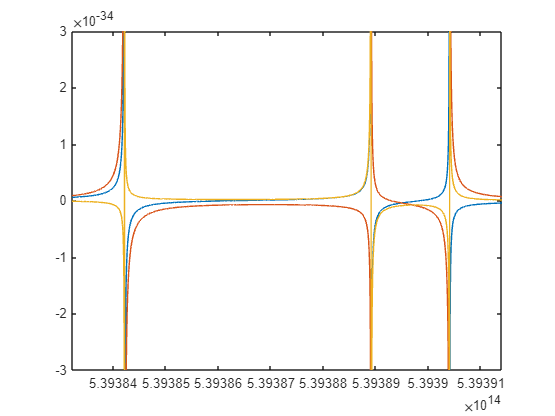

figure;
for rank=0:1:2
plot(light_freq,polarizability(rank+1,:));
hold on
end
ylim([-3e-34,3e-34]);
xlim([min(light_freq) max(light_freq)]);

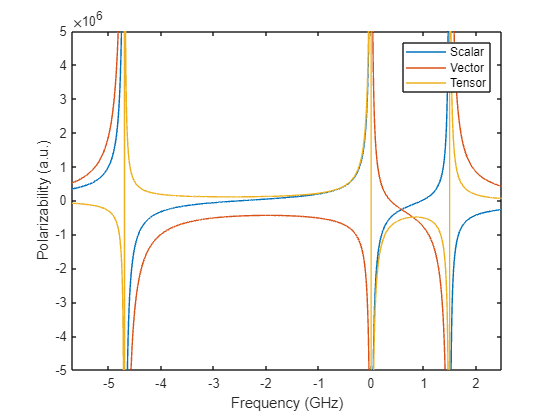



polarizability_inau=polarizability./(4*pi*epsilon0)./(a0^3);

figure;
xaxis=(light_freq-omega_trans(5/2)/2/pi)*1E-9;
for rank=0:1:2
plot(xaxis,polarizability_inau(rank+1,:));
hold on
end
legend("Scalar","Vector","Tensor");
ylabel("Polarizability (a.u.)");
xlabel("Frequency (GHz)");
ylim([-5e6,5e6]);
xlim([min(xaxis) max(xaxis)]);

function polarizability=polar(rank,light_freq)
    polarizability=0;
    a0= 5.2917721067e-11; % Bohr Radius
    hbar=1.05457266*10^-34;
    electron=1.602e-19;
    matrix_element=0.54*a0*electron;
    for F=3/2:1:7/2
        adddition=(-1)^(F+5/2)*(2*F+1)*Wigner6j(1,rank,1,5/2,F,5/2)*(Wigner6j(5/2,1,F,1,5/2,0))^2/hbar*(1/(omega_trans(F)-2*pi*light_freq));
        polarizability=polarizability+adddition;        
    end
    polarizability=polarizability*(-1)^(rank+1)*(5/2*2+1)*sqrt(2*rank+1)*matrix_element^2;
    if rank==0
        polarizability=polarizability/(sqrt(3*(2*5/2+1)));
    elseif rank==1
        polarizability=-polarizability*sqrt(2*5/2/((5/2+1)*(2*5/2+1)));
    elseif rank==2
        polarizability=-polarizability*sqrt((2*5/2*(2*5/2-1))/(3*(5/2+1)*(2*5/2+1)*(2*5/2+3)));
    end
end
%%
function omega=omega_trans(F)
    ref_freq=539390406.83*10^6;        % 171:1/2-3/2
    ref_freq0=ref_freq-4759.440*10^6;   % 176
    if F==5/2
        omega=ref_freq0+3266.243*10^6;
        
    elseif F==7/2
        omega=ref_freq0-1431.872*10^6;
    elseif F==3/2
        omega=ref_freq0+4762.110*10^6;
    else
        disp("Wrong input");
        omega=0;
    end
    omega=omega*2*pi;
end